# 요약

## 1. Reference code에 포함된 내용

- spike detection algorithm

- cluster average waveform with confidence band

- raster plot

- colored raster plot

- PCA

- kmeans

- calculation of discrete derivative(dV/dt)

- ISI(interspike interval) plot

## 2. Reference code에 포함되지 않아서 제가 추가한 내용

- Baw data file을 불러와서 정리하여 array로 바꾸는 함수

- Bandpass filter 적용을 위한 resampling과 [300hz, 3000hz] bandpass filter 적용

- Bandpass filter 적용을 통한 theta wave 획득 및 Hilbert transform을 통한 theta phase 계산

- circstat 패키지를 이용한 theta phase 분포 plot 및 phase lock test

- phase-space plot

- FWHm(full width half minimum) 계산 및  month 단위로 합쳐서 bar plot으로 비교

## 3. Reference code를 변경한 내용

- 기존 코드는 sampling frequency 30000에 맞춰서 모든 코드가 구성되어 있어서, sampling frequency가 다른 데이터에 적용하면 제대로 작동하지 않았음(ms <-> timestamp 간 변환 관련) -> 데이터의 sampling frequency를 자동으로 계산하고, 계산한 값에 맞추어 다른 알고리즘이 동작하도록 수정

- PCA 수행 시 standardization 시행

- k-means 수행 시 seed number 사용

- 여러 채널의 데이터를 효율적으로 관리하고 관련 데이터와 변수를 한 곳에 모아 놓기 위해 class 제작: channel이라는 object에 데이터 파일 하나의 raw data, filtered data, PCA 및 kmeans 결과 등이 저장됨

- plotting도 object를 통해 수행하도록 함:

- 간단한 plotting의 경우 object에서 얻은 데이터를 matlab 함수를 사용해 직접 plotting

- 복잡한 plottin의 경우 object에 내장시킨 metho를 통해 plotting하도록 설계

## 4. 파일 목록

- CyborgBrainOrg.m : 원본 reference code를 주어진 데이터에서 돌아가도록 수정완료한 파일

- channel.m : 데이터 및 변수의 효율적 관리를 위해 만든 channel class 정의 파일. CyboarBrainOrg.m의 내용이 리팩토링되어 들어가 있음

- longtermAnalyzer.m: 여러 organoid, channel, month 데이터를 통합 관리하고 month 별로 묶어 plotting하기 위해 만든 longtermAnalyzer class 정의 파일

## 5. 필요한 애드온 목록

- Statistics and Machine Learning Toolbox

- Signal Processing Toolbox

- Bioinformatics Toolbox

- Circular Statistics(by Philipp Berens)

## 6. 구현 못한 plot

- figure 4.e figure 2.o에서 FWHm만 signal power로 바꾸면 됨. signal power를 matlab에서 계산하는 방법을 아직 찾지 못함

- figure 4.h는 figure 2.o에서 FWHm만 spikes count per neuron으로 바꾸면 됨.

- figure 4.i

# channel class 설명 및 논문의 데이터 처리 재현과 코멘트

## channel object 생성 및 데이터 처리

**1. channel object 생성: 데이터 불러오기 및 resampling 수행**

object를 생성할 때 데이터를 불러오고 bandpass filter 적용을 위한 resampling을 수행

parameter 4개

- 파일이름: 같은 디렉토리일 경우 파일이름만, 다른 디렉토리일 경우 전체 경로 포함 입력

- organoid: organoid 번호

- channel: channel 번호

- month: month. 나중에 month별로 종합할 때 사용됨

                     %file name,  organoid, channel, month 
o1_ch8_m1 = channel("rawData.csv", 1, 8, 1);

**2. bandpass filter 적용**

파라미터 1개 

- passBand : [숫자, 숫자] 포맷으로, hz 단위로 입력

현재 데이터를 frequency domain으로 변환시 2000hz 이상 부분이 없어서 경고 메시지가 뜸

o1_ch8_m1.bandPass([300,3000]); %apply bandpass filter 300-3000hz

**3. spike detection 수행**

paramter 3개

- thres: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류 ((reference code에서는 5)

- preTime: spike waveform의 spike 앞쪽 너비. milisecond 단위 (reference code에서는 2)

- postTime: spike waveform의 spike 뒷쪽 너비. milisecond 단위 (reference code에서는 2)

                        %thres, preTime, postTime
o1_ch8_m1.detectSpikes(5,2,2);

**4. PCA 수행**

주의

- PCA는 각 축의 분산을 최대한 보존하는 principal component를 찾는 알고리즘이므로, 특정 waveform의 scale이 지나치게 크다면 분산에 많이 기여하게 되어 그 waveform을 principal component로 잘못 인식할 수 있음. 일반적으로 PCA를 비롯한 차원축소 알고리즘들이 비슷한 문제를 가지고 있기 때문에, 알고리즘 수행 전에 각 데이터포인트의 scale을 통일하는 scaling을 필수적으로 수행함

- Scaling 방법은평균을 빼고 표준편차로 나누는 standard scaling, min을 빼고 (max-min)으로 나누는 0-1 scaling 등이 있음

- 물론 데이터가 scale이 원래 일정하다면 굳이 standardization을 수행할 필요가 없음. Reference code에서는 standard scaling 코드를 써 놓고 주석 처리해 놓았음. 이 코드에서는 주석 처리를 해제하고 standard scaling을 수행하도록 하였음

- PCA 수행 후 explained variance plot을 꼭 확인해야 함. 첫 두 PC가 설명하는 분산의 양이 충분히 커야(보통 70% 이상) 2차원만 남기고 나머지 차원을 버리는 것이 정당화됨

o1_ch8_m1.getPCScores();

**5. K-means clustering 수행**

parameter 2개

- clusternum: cluster 개수(reference code에선 3)

- seednum: 알고리즘의 초기값에 영향을 미치는 random number seed(reference code에 없음)

주의

- k-means clustering은 해를 해석적으로 구하지 못하고 EM algorithm이라는 iterative algorithm을 사용하는데, 초기값에 큰 영향을 받음. 초기값이란 각 점의 맨 처음 cluster 배정을 의미하며, 랜덤으로 할당함. 일반적으로 이러한 EM algorithm 기반 clustering을 수행할 때는 여러 seed number를 사용하여 알고리즘을 여러 번 돌려봄.

- k-means clustering에서 cluster 개수(clusternum)는 자동으로 최적값이 정해지지 않으며, 정답이 없는 비지도학습이기에 최적값을 알 수도 없음. 일반적으로 사용자가 여러 clusternum을 시도해 보며 적절한 값을 찾아야 함.

- 결론적으로, 여러 clusternum과 seednum의 조합을 시도하면서 plot을 보고 사용자 눈에 적절한 결과가 나올때까지 진행해야 함.

                           %clusternum, seednum
o1_ch8_m1.getKmeansClusters(3,1);

6. theta wave 및 theta angle 계산

논문에 나온 대로 계산

- theta wave: raw trace에 4-8hz bandpass 적용

- theta angle: theta wave에 hilbert transform 적용 후 실수부와 허수부 사이의 angle을 계산

o1_ch8_m1.getThetas();

# 논문 plot 재현 및 코멘트

## Figure 2.f.

figure 2.b-d는 2.f.와 같은 내용.

raw trace, filtered trace, raster polot

**channel object에서 데이터 접근 방법**

- **channelobject.t** : time array

- **channelobject.raw**: raw trace array

- **channelobject.filtered**: filtered trace array

이후 matlab 기본 plot 함수 사용

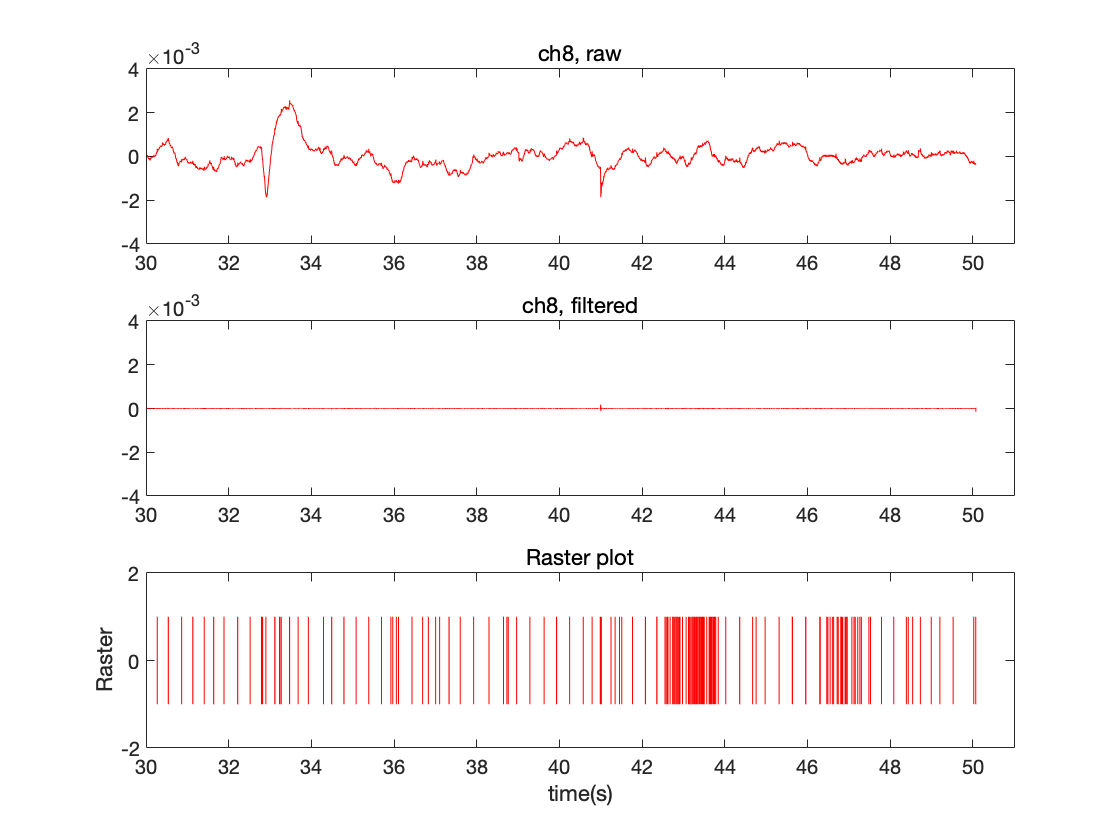

figure

%raw trace plot
subplot(3,1,1)
pRaw = plot(o1_ch8_m1.t, o1_ch8_m1.raw);
pRaw.Color = 'red'; %색깔 조절 가능
title('ch8, raw'); %제목
ylim([-4,4]*1e-3);%ylim 조절 가능
xlim([30,51]); %xlim 조절 가능

%filtered trace plot
subplot(3,1,2)
pFiltered = plot(o1_ch8_m1.t, o1_ch8_m1.filtered);
pFiltered.Color = 'red';%색깔 조절 가능
title('ch8, filtered');
ylim([-4,4]*1e-3);%ylim 조절 가능
xlim([30,51]); %xlim 조절 가능

%raster plot of spike locations
subplot(3,1,3) %제목
o1_ch8_m1.drawRaster('red');%색깔 조절 가능
xlim([30,51]); %xlim 조절 가능

## Figure 2.g.

figure 2.e와 같은 내용

filtered trace에서 찾은 spike의 위치를 raw trace와 filtered trace에서 zoom in

여기서는 예제로 첫번째 spike의 위치를 zoom in

**channel object에서 데이터 접근 방법**

- **channelobject.spikeTimestamps**: filtered trace에서 찾아낸 spike들의 위치(timestamp 단위)

- **channelobject.timestampsPrePeak**: spike waveform의 전반부 너비(timestamp 단위. reference code에선 60, 여기선 7. 2milisecond를 samplin frequency에 따라 timestamp로 환산한 것.)

- **channelobject.timestampsPostPeak**: spike waveform의 후반부 너비(timestamp 단위)(timestamp 단위. reference code에선 60, 여기선 7. 2milisecond를 samplin frequency에 따라 timestamp로 환산한 것.)

이후 matlab 기본 plot 함수 사용

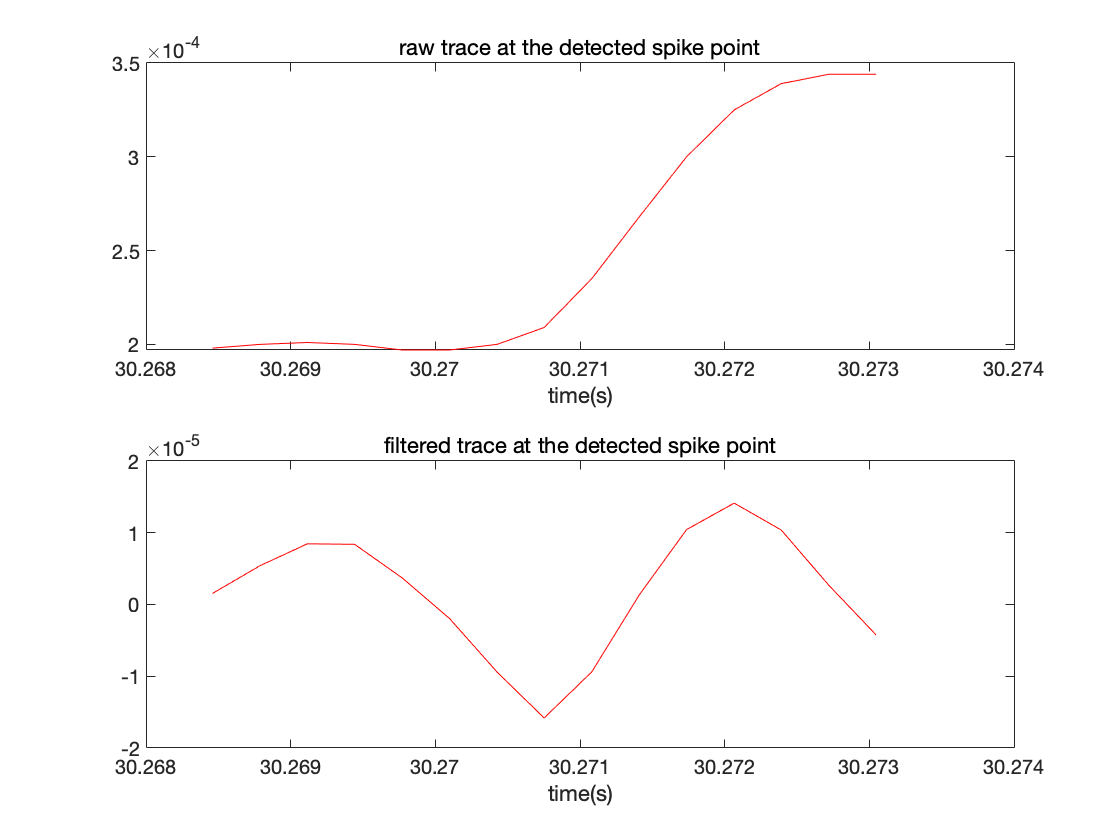


spikeTimestamps = o1_ch8_m1.spikeTimestamps; %spike 위치 가져오기
ts = spikeTimestamps(1); %첫번째 spike의 위치 가져오기
tsInterval = ts + (-o1_ch8_m1.timestampsPrePeak : o1_ch8_m1.timestampsPostPeak);
%spike를 중심으로 waveform의 t축 범위를 정함

figure

%raw trace zoom in
subplot(2,1,1)
pRaw = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.raw(tsInterval));
pRaw.Color = 'red';%색깔 조절 가능
title('raw trace at the detected spike point');
xlabel('time(s)');

%filtered trace zoom in
subplot(2,1,2)
pFiltered = plot(o1_ch8_m1.t(tsInterval), o1_ch8_m1.filtered(tsInterval));
pFiltered.Color = 'red';%색깔 조절 가능
title('filtered trace at the detected spike point');
xlabel('time(s)');

## Figure 2.h

PCA 및 kmeans 결과, 각 cluster별 average spike 모양

- explained variance plot: 첫 두 막대의 높이 합이 충분이 큰지 확인(이 예제에서는 약 80으로 양호).

- PCA/kmeans scatterplot: 결과를 보면서 여러 clusternum과 seednum 시도

- mean spike: 논문과 같이 y축 scale 통일함.

**plot 그리는 함수 이름**

- **channelobject.drawPCA(): **PCA explained varaiance plot과 PCA/kmeans scatterplot

- **channelobject.drawClusterMeanSpikes()**: 각 cluster별 mean spike waveform plot

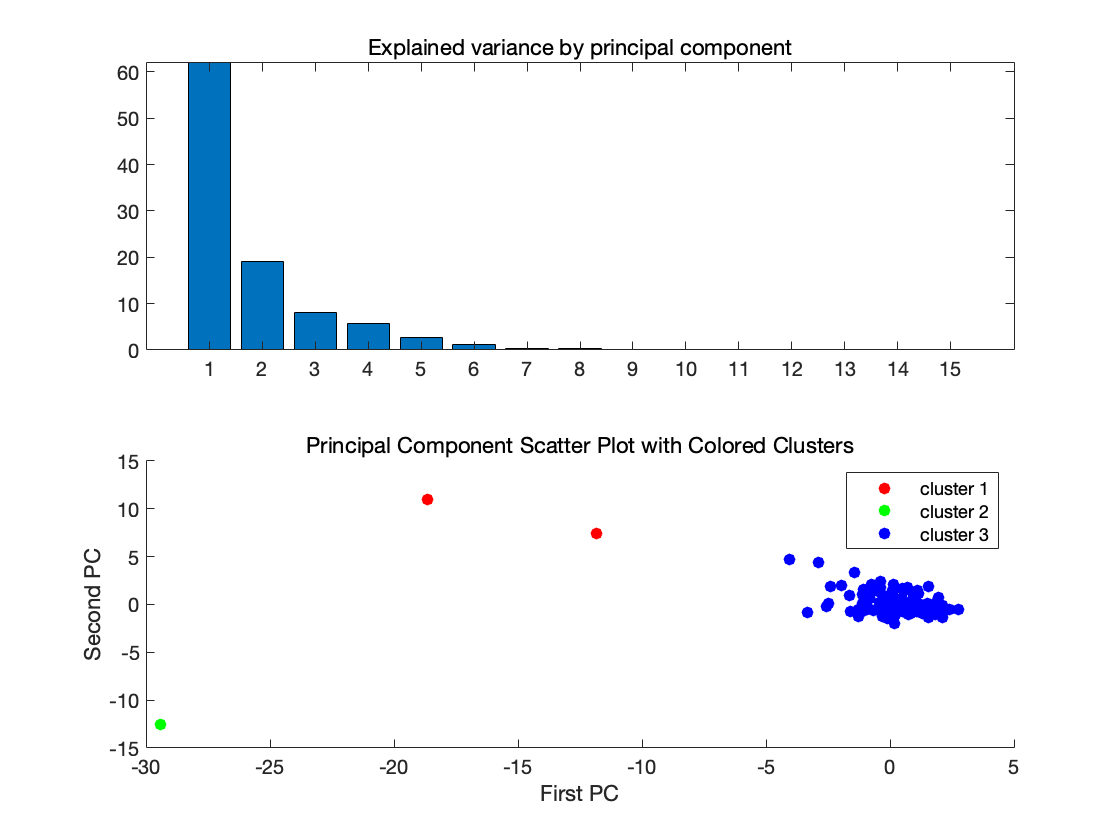

figure
o1_ch8_m1.drawPCA()

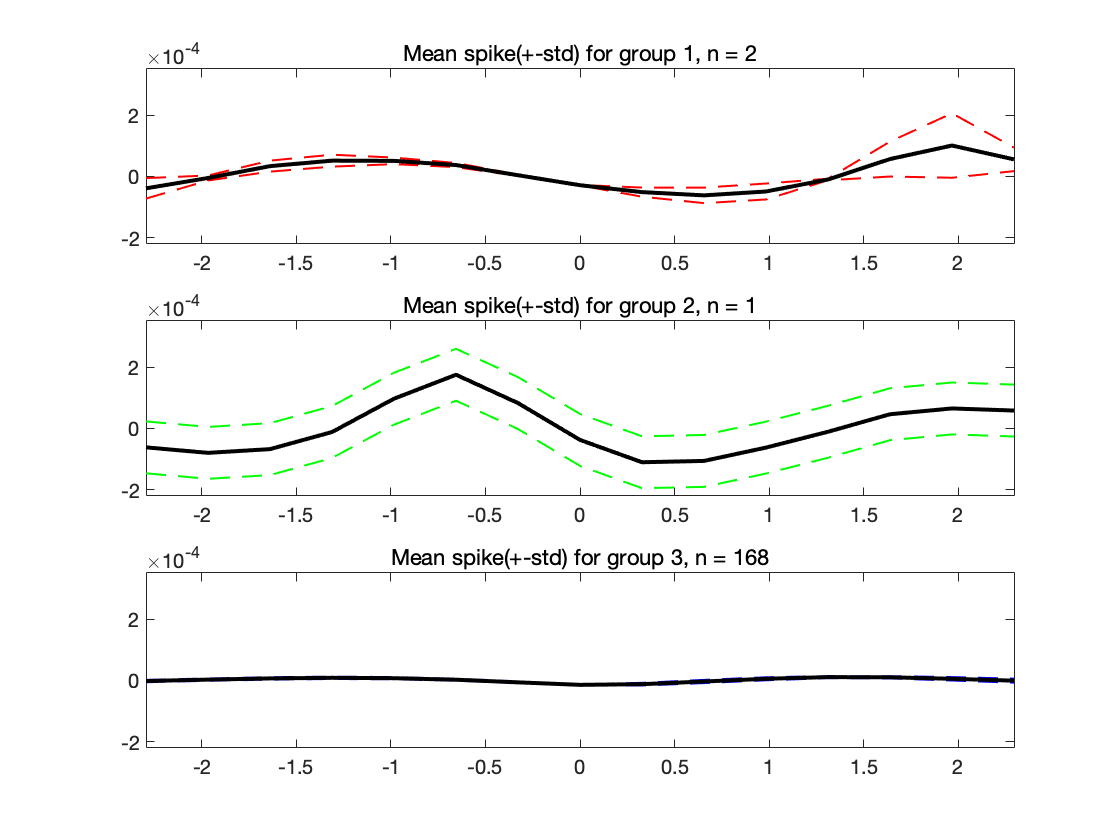


figure
o1_ch8_m1.drawClusterMeanSpikes();

## Figure 2.i

colored raster plot. 클러스터 3개일 때는 파란색이 압도적으로 많아 구분이 잘 되지 않으므로, 일시적으로 클러스터 5개로 수정

**plot 그리는 함수 이름**

- **channelobject.drawColoredRaster():** 클러스터별로 색이 다르게 입혀진 raster plot. spike의 위치를 표시.

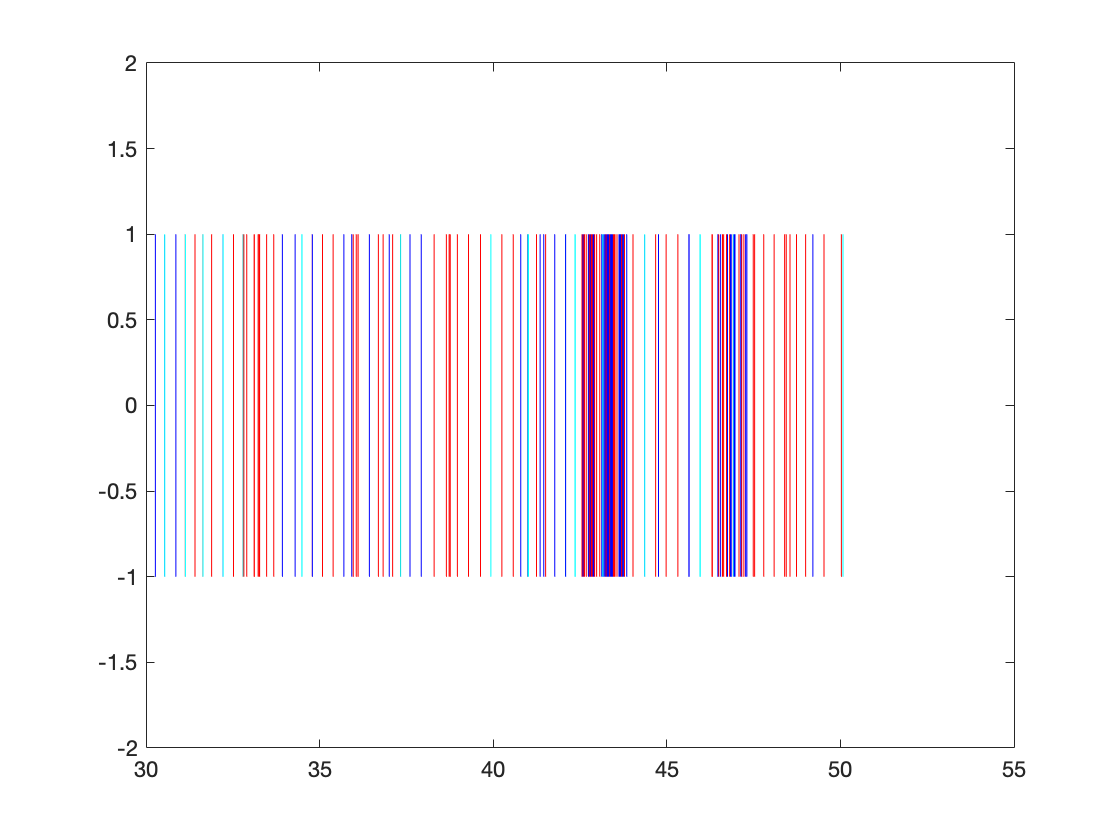

o1_ch8_m1.getKmeansClusters(5,1);
figure
o1_ch8_m1.drawColoredRaster();

o1_ch8_m1.getKmeansClusters(3,1);

## Figure 2.j.

interspike intervals histogram

이 예제에서는 cluster 1과 2의 원소가 거의 없으므로 히스토그램이 제대로 그려지지 않음

**plot 그리는 함수 이름**

- **channelobject.drawISI()**: interspike intervals(spike 간 time interval)의 히스토그램.

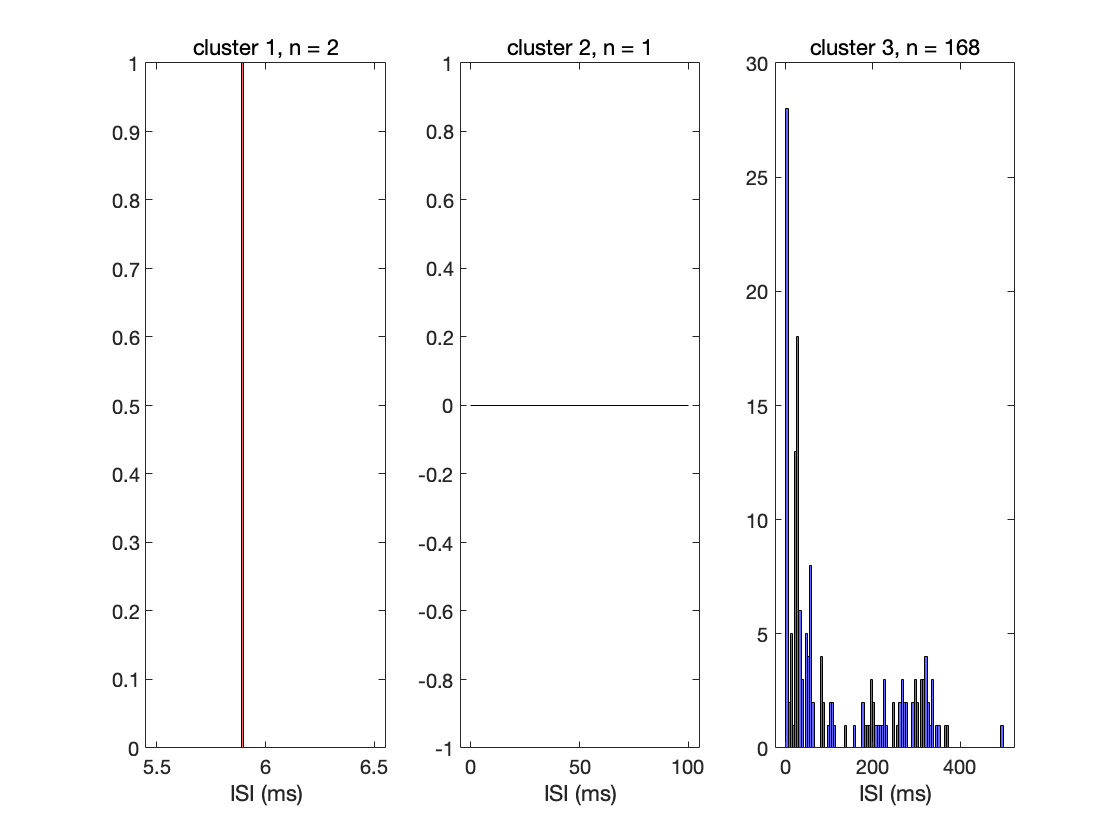

figure
o1_ch8_m1.drawISI();

## Figure 2.k

theta waves and theta phase

thetaPhase의 경우, y축 범위가 (-pi, pi)임. 논문에서는 y축 스케일을 줄여 놓아 trace 모양이 잘 드러나게 하였음. 여기서는 원본 스케일을 써서 논문과 다르게 보임. matlab의 plot함수의 옵션을 사용하여 조절 가능.

**channel object에서 데이터 접근 방법**

- **channelobject.thetaWaves**: theta wave trace array

- **channelobject.thetaPhases**: theta angle array

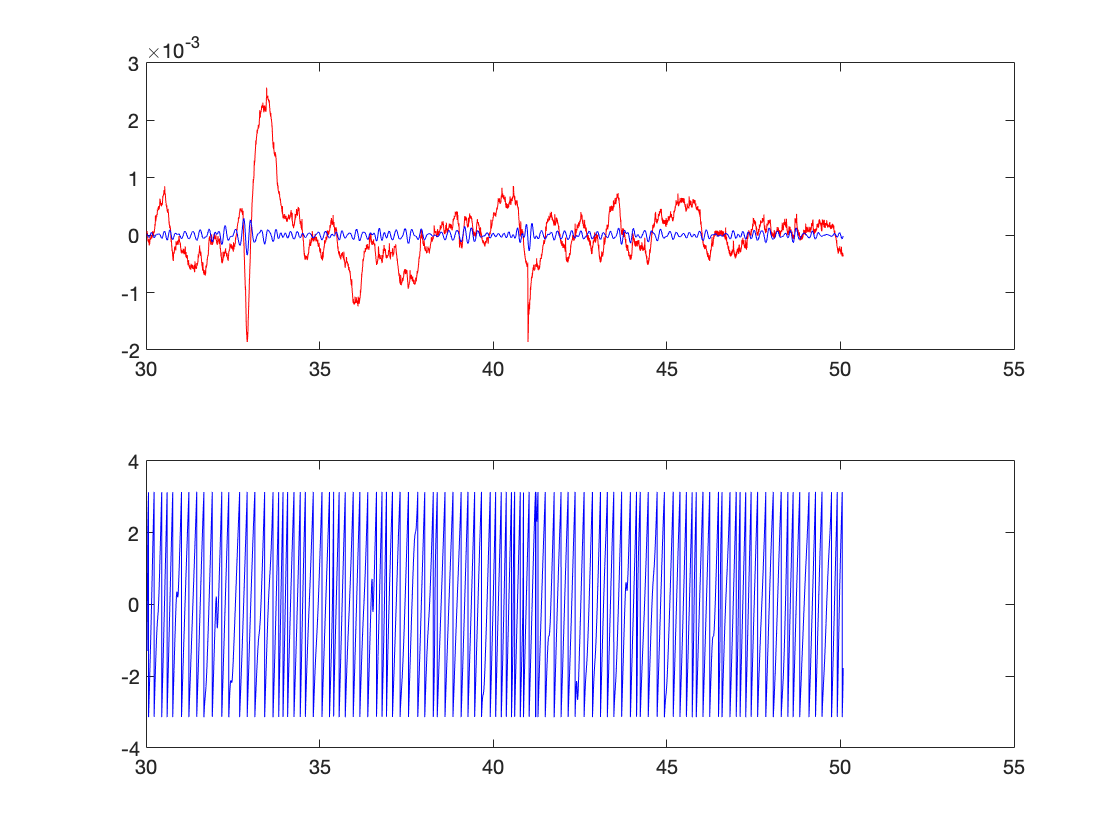

figure
subplot(2,1,1)
p_raw = plot(o1_ch8_m1.t, o1_ch8_m1.raw);
p_raw.Color = 'red'; %색깔 조절

hold on;

p_thetaWaves = plot(o1_ch8_m1.t, o1_ch8_m1.thetaWaves);
p_thetaWaves.Color = 'blue'; %색깔 조절

hold off;

subplot(2,1,2)
p_thetaPhases = plot(o1_ch8_m1.t, o1_ch8_m1.thetaPhases);
p_thetaPhases.Color = 'blue'; %색깔 조절

## Figure 2.m

Circular distribution of theta angles

**plot 그리는 함수 이름**

- **channelobject.drawCircularTheta()**: theta angle 분포를 원형 히스토그램으로 그림

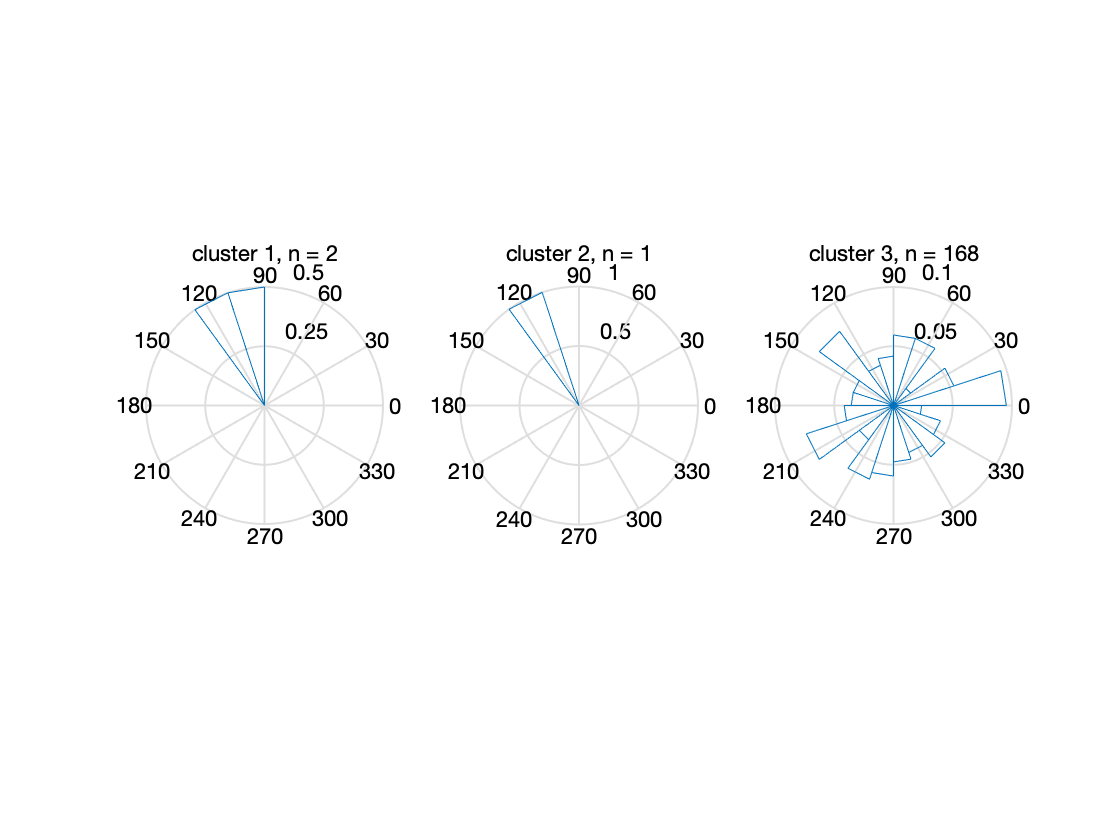

figure
o1_ch8_m1.drawCircularTheta();

## Figure 2.n. 

distrubution of theta angles at spikes

**plot 그리는 함수 이름**

- **channelobject.drawThetaHist()**: cluster별로 spike에서의 theta angle 분포를 일반 히스토그램으로 그램

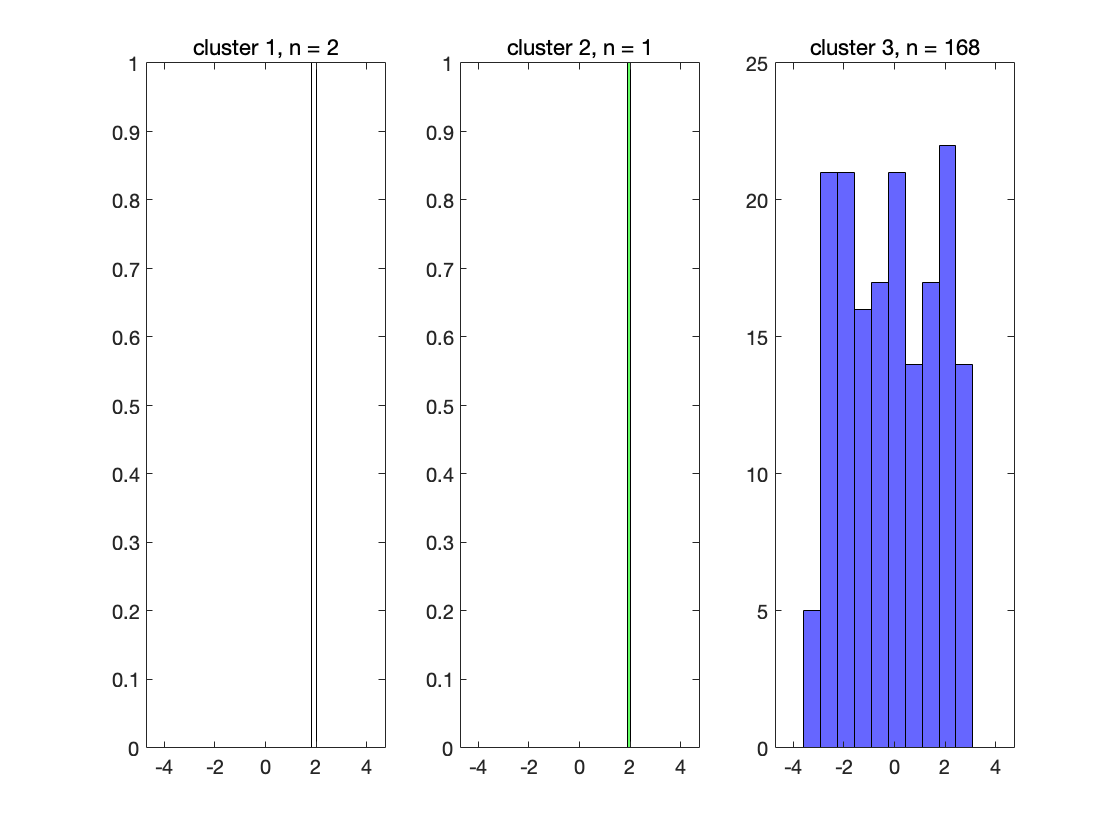

figure
o1_ch8_m1.drawThetaHist();

## Uniform test(phase-locking detection)

testing the non-uniformty of theta phase distribution using Rayleigh criterion to detect phase-locking.

We considered that phase-locking to theta waves happens for P-values below 0.05.

- phase-locking: theta wave의 특정 phase에서 spike가 유독 많이 일어나는 현상. Phase-locking이 없다면, spike에서의 theta angle분포는 uniform 분포를 따를 것. 따라서 theta angle 분포가 uniform distribution과 같은지 가설검정을 수행. 논문에서는 p-value 기준 0.05를 사용. 0.05보다 작으면 phase-locking. 0.05보다 크면 phase-locking 없는 것으로 판단.

**test 수행하는 함수 이름**

- **channelobject.uniformTest()**: cluster 순서대로 p-를 출력.

o1_ch8_m1.uniformTest()

pvals =     0.1397
    0.4658
    0.9354


# longtermAnalyzer 클래스 소개 및 plot 재현

월별 비교를 위해 여러 channel의 데이터를 모아서 관리하는 class

일단 여러개의 data file을 불러오고, data 처리를 진행

%불러오기 

%organ, ch, month
o1_ch1_m1 = channel("rawData.csv", 1, 1, 1);
o1_ch2_m1 = channel("rawData.csv", 1, 2, 1);
o2_ch1_m1 = channel("rawData.csv", 2, 1, 1);
o2_ch2_m2 = channel("rawData.csv", 2, 2, 2);
o3_ch1_m2 = channel("rawData.csv", 3, 1, 2);
o2_ch1_m2 = channel("rawData.csv", 2, 1, 2);

%bandpass filter
o1_ch1_m1.bandPass([300,3000]);

o1_ch2_m1.bandPass([300,3000]);

o2_ch1_m1.bandPass([300,3000]);

o2_ch2_m2.bandPass([300,3000]);

o3_ch1_m2.bandPass([300,3000]);

o2_ch1_m2.bandPass([300,3000]);


%spike detection
o1_ch1_m1.detectSpikes(3,2,2);
o1_ch2_m1.detectSpikes(3,2,2);
o2_ch1_m1.detectSpikes(3,2,2);
o2_ch2_m2.detectSpikes(3,2,2);
o3_ch1_m2.detectSpikes(3,2,2);
o2_ch1_m2.detectSpikes(3,2,2);

%theta calculation
o1_ch1_m1.getThetas();
o1_ch2_m1.getThetas();
o2_ch1_m1.getThetas();
o2_ch2_m2.getThetas();
o3_ch1_m2.getThetas();
o2_ch1_m2.getThetas();

**longtermAnalyzer object 생성**

- **LAobject.addChannel(channelobject)**: 데이터 처리 완료한 channel object를 longtermAnalyzer object에 추가

la = longtermAnalyzer(); %longtermAnalyzer object 생성

%channel object 추가
la.addChannel(o1_ch1_m1);
la.addChannel(o1_ch2_m1);
la.addChannel(o2_ch1_m1);
la.addChannel(o2_ch2_m2);
la.addChannel(o3_ch1_m2);
la.addChannel(o2_ch1_m2);

## Figure 2.o

월별 히스토그램. 

channel을 지정하면 월별로 모든 organoid를 aggregate.

spike waveform 너비를 논문과 똑같이 +-2ms로 하면, 이 예제에서는 sampling frequency 가 약 3000으로 논문의 30000에 비해 작기 때문에

waveform 너비가 15 timestamp밖에 되지 않음. 따라서 FWHm(Full width at half minimum)의 가능한 값의 종류가 한정되어 있음. 이 때문에 organoid별로 FWHm 값의 종류가 거의 같게 되어, 그래프에서 점이 다 겹처서 organoid 2밖에 보이지 않음.

**plot 그리는 함수 이름**

- **LAobject.drawFWHmHistByMonth(channelNum)**: channelNum으로 지정한 channel에서 월별로 모든 organoid의 데이터를 합쳐서 FWHm의 평균을 bar plot으로 그림

내부에서 FWHm 계산하는 함수 이름

- **LAobject.FWHm(spikeWaveform, msPerTs): **spikewaveform에서 minimum 값의 절반을 계산한 뒤, 그 값보다 작은 값이 나온 첫 번째 timestamp와 마지막 timestamp를 찾아서 그 너비를 milisecond로 환산. Spike가 unimodal이 아닐 경우 FWHm값이 크게 나올 수 있음.

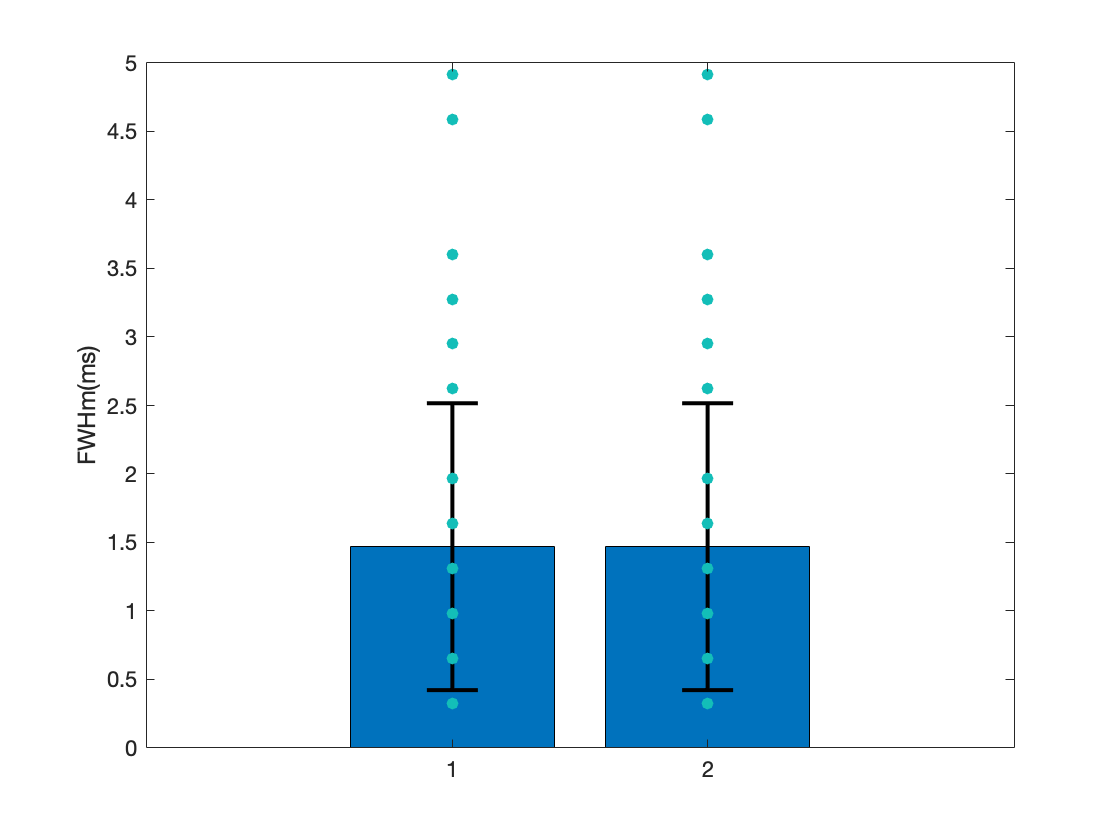

figure
la.drawFWHmHistByMonth(1) %channel 1으로 지정

## Figure 2.p.

phase-space analysis

figure 4.f와 동일

## Figure 2.q.

월별 cluster 개수 비교

월별 mean spike by clusters

월별 colored raster plot

앞의 plot 방법들을 조합하여 해결 가능

## Figure 4.b.

여러 데이터 불러오기

                             %organoid, channel, month     
o1_ch1_m1 = channel("rawData.csv", 1, 1, 1);
o1_ch2_m1 = channel("rawData.csv", 1, 2, 1);
o1_ch1_m2 = channel("rawData.csv", 1, 1, 2);
o1_ch2_m2 = channel("rawData.csv", 1, 2, 2);

100-3000hz로 필터링

o1_ch1_m1.bandPass([100,3000])

o1_ch2_m1.bandPass([100,3000])

o1_ch1_m2.bandPass([100,3000])

o1_ch2_m2.bandPass([100,3000])

cluster 개수 3개, spike waveform 길이 +- 2ms로 spike detection 실행

o1_ch1_m1.detectSpikes(3,2,2)
o1_ch2_m1.detectSpikes(3,2,2)
o1_ch1_m2.detectSpikes(3,2,2)
o1_ch2_m2.detectSpikes(3,2,2)

channel object별로 raw trace 그리기. ylim 옵션을 이용해 비교대상끼리 y축 스케일 통일.

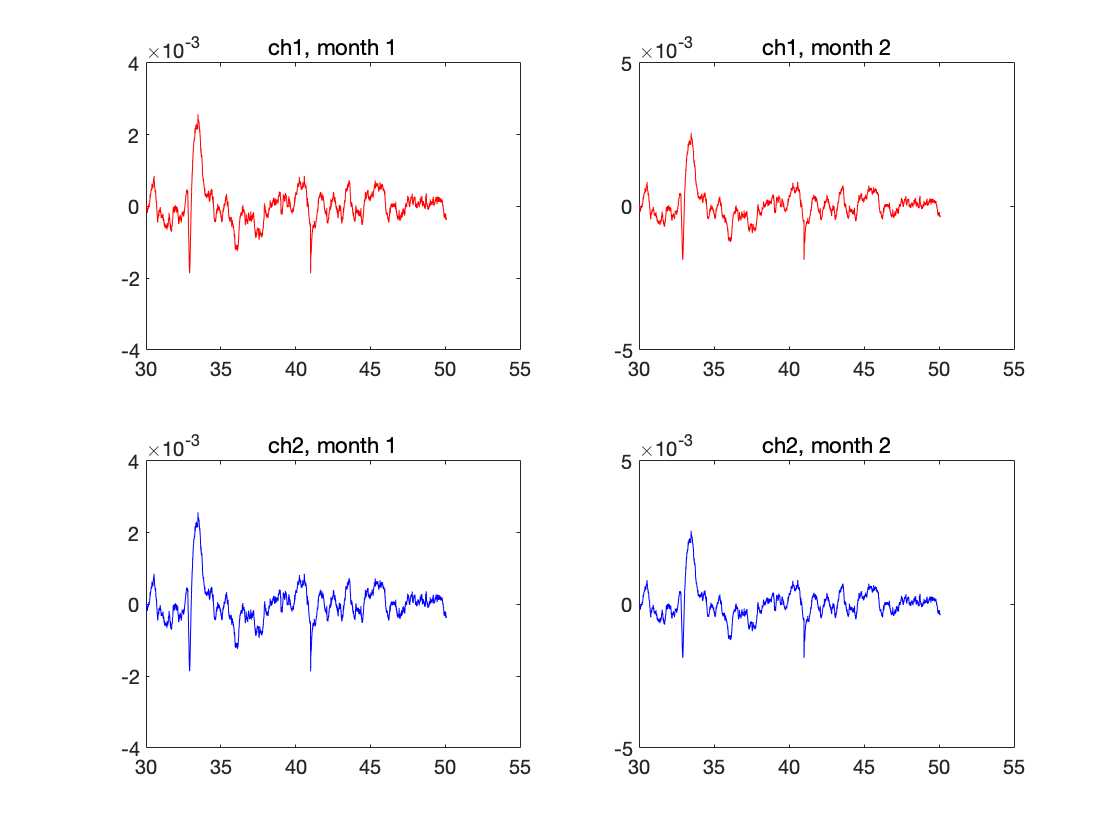

figure
%month 1

%ch1
subplot(2,2,1)
p = plot(o1_ch1_m1.t, o1_ch1_m1.raw);
p.Color = 'red';
title('ch1, month 1');
ylim([-4,4]*1e-3);%ylim 조절

%ch2
subplot(2,2,3)
p_o1_ch2_m1 = plot(o1_ch2_m1.t, o1_ch2_m1.raw);
p_o1_ch2_m1.Color = 'blue';
title('ch2, month 1');
ylim([-4,4]*1e-3);%ylim 조절


%month 2
%ch1
subplot(2,2,2)
p_o1_ch1_m2 = plot(o1_ch1_m2.t, o1_ch1_m2.raw);
p_o1_ch1_m2.Color = 'red';
title('ch1, month 2');
ylim([-5,5]*1e-3);%ylim 조절

%ch2
subplot(2,2,4)
p_o1_ch2_m2 = plot(o1_ch2_m2.t, o1_ch2_m2.raw);
p_o1_ch2_m2.Color = 'blue';
title('ch2, month 2')
ylim([-5,5]*1e-3);%ylim 조절

channel object별로 mean spike 그리기.

**plot 그리는 함수 이름**

- **channelobject.drawMeanSpike(color)**: channel의 mean spike(cluster 구분 없이)를 그림. 색상 지정 가능.

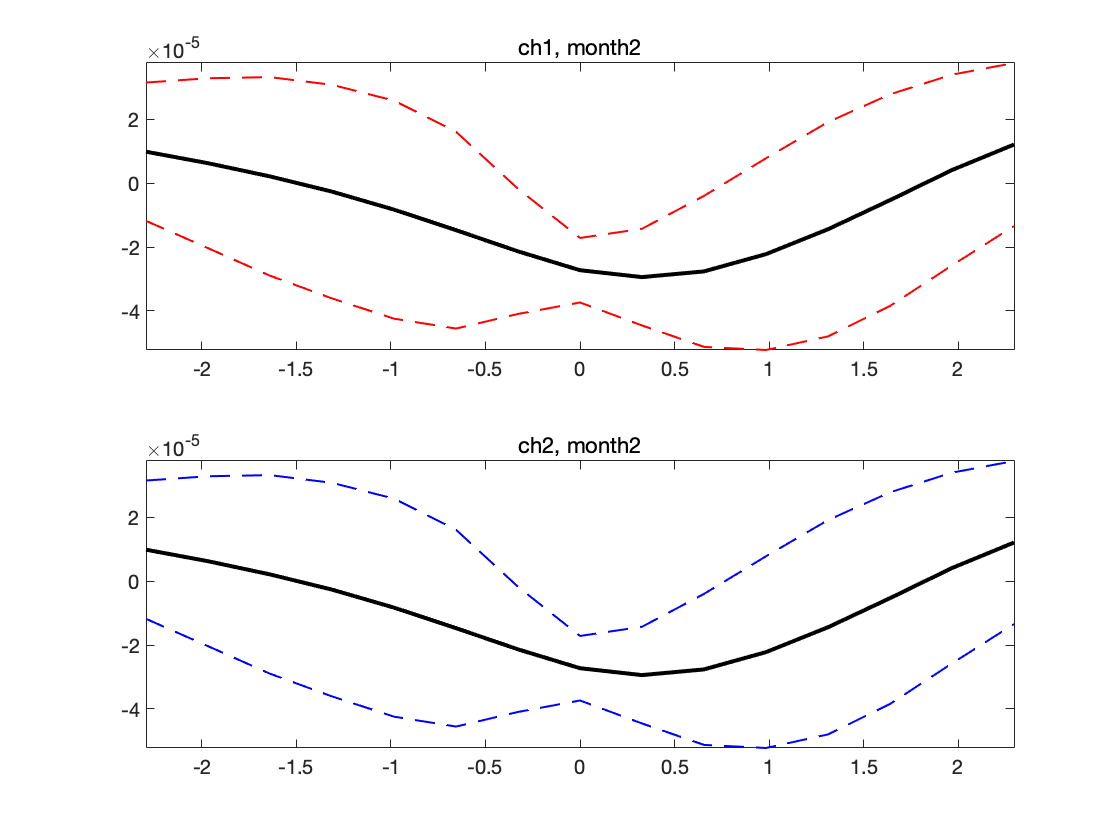

figure
subplot(2,1,1)
o1_ch1_m2.drawMeanSpike('red'); %색깔 지정
title('ch1, month2');
subplot(2,1,2)
o1_ch2_m2.drawMeanSpike('blue');%색깔 지정
title('ch2, month2');

## Figure 4.c.

spectrogram

x축 0s = 데이터 시작 시간(이 데이터에서는 약 30s)

matlab signal processing toolbox의 spectrogram 함수 사용

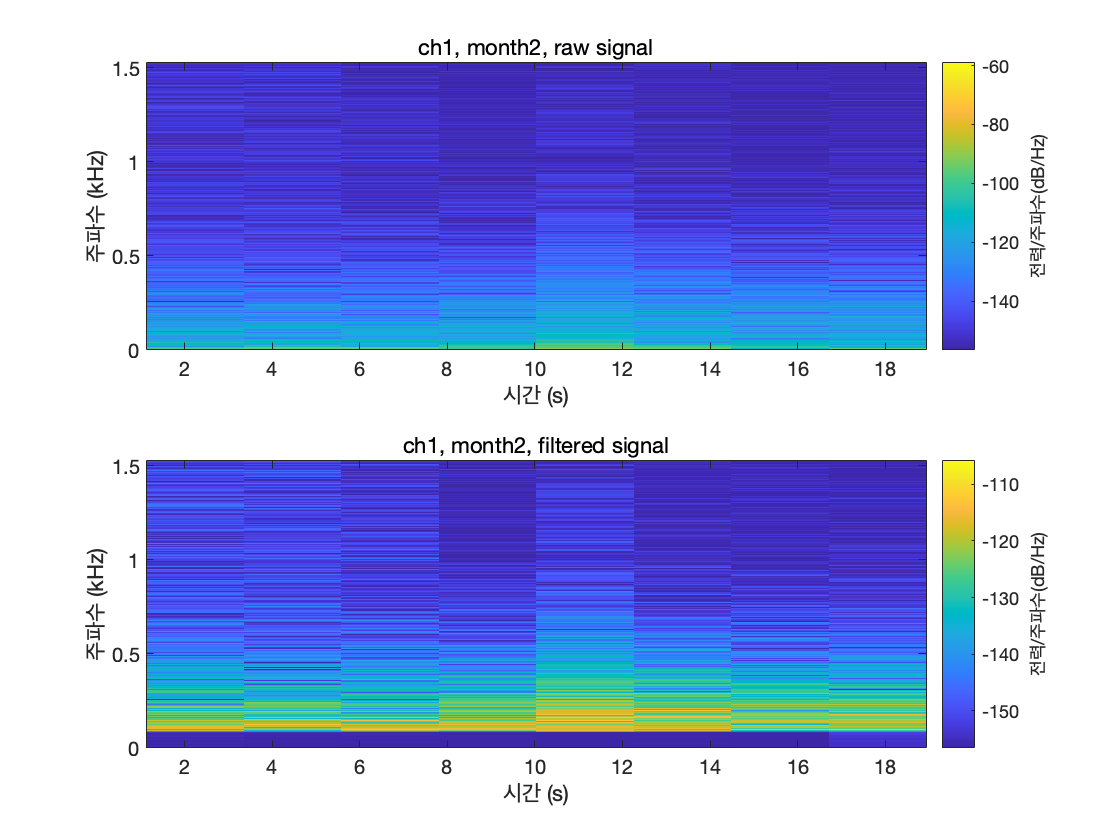

figure
subplot(2,1,1)
spectrogram(o1_ch1_m2.raw, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, raw signal')

subplot(2,1,2)
spectrogram(o1_ch1_m2.filtered, [], [], [], o1_ch1_m2.sf, 'yaxis')
title('ch1, month2, filtered signal')

## Figure 4.d

power spectrums

signal processing toolbox의 pspectrum 함수 사용

논문에서는 여러 month의 raw data를 비교하지만, 이 예제에서는 데이터 파일이 하나밖에 없으므로 플롯에서 구분이 되도록 month2에서는 filtered data를 사용

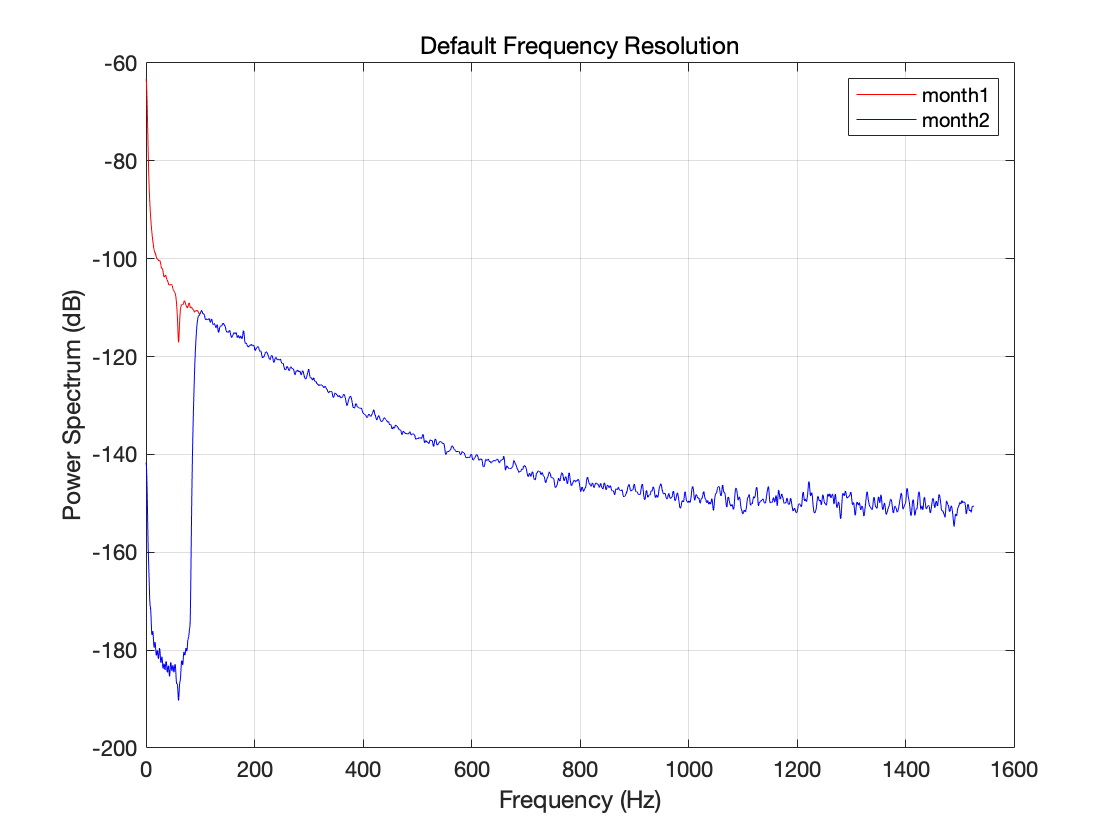

figure

xTable = timetable(seconds(o1_ch1_m1.t), o1_ch1_m1.raw); %raw data
[pxx,f] = pspectrum(xTable);
month1 = plot(f,pow2db(pxx));
month1.Color = 'red';

hold on

xTable = timetable(seconds(o1_ch1_m2.t), o1_ch1_m2.filtered); %filtered data
[pxx,f] = pspectrum(xTable);
month2 = plot(f,pow2db(pxx));
month2.Color = 'blue';

grid on

legend('month1', 'month2');
xlabel('Frequency (Hz)');
ylabel('Power Spectrum (dB)');
title('Default Frequency Resolution');

## Figure 4.f.

phase-space analysis

원 논문에서는 sampling frequency가 30000으로 높아서, spike +- 2ms가 121개의 timestamp로 구성되므로(앞으로 60, 뒤로 60) trajectory의 모양이 복잡함(121 steps)

본 예제에서는 sampling frequency가 약 3000으로 낮아서, spike +- 2ms가 15개의 timestamp로 구성되므로(앞으로 7, 뒤로 7. 반올림 때문) trajectory의 모양이 단순함(15 steps)

이 예제애서는 둘의 trajectory가 똑같아서 파란색만 보임

**plot 그리는 함수 이름**

- **channelobject.drawPhaseSpace(color)**: channel의 dVdt - V trajectory를 그림. 색상 지정 가능.

figure
o1_ch1_m1.drawPhaseSpace('red')

V = 	1.0e+-4 *

    0.3926    0.3566    0.3152    0.2676    0.2113    0.1470    0.0806    0.0216         0    0.0179    0.0719    0.1498    0.2409    0.3352


hold on
o1_ch1_m2.drawPhaseSpace('blue')

V = 	1.0e+-4 *

    0.3926    0.3566    0.3152    0.2676    0.2113    0.1470    0.0806    0.0216         0    0.0179    0.0719    0.1498    0.2409    0.3352


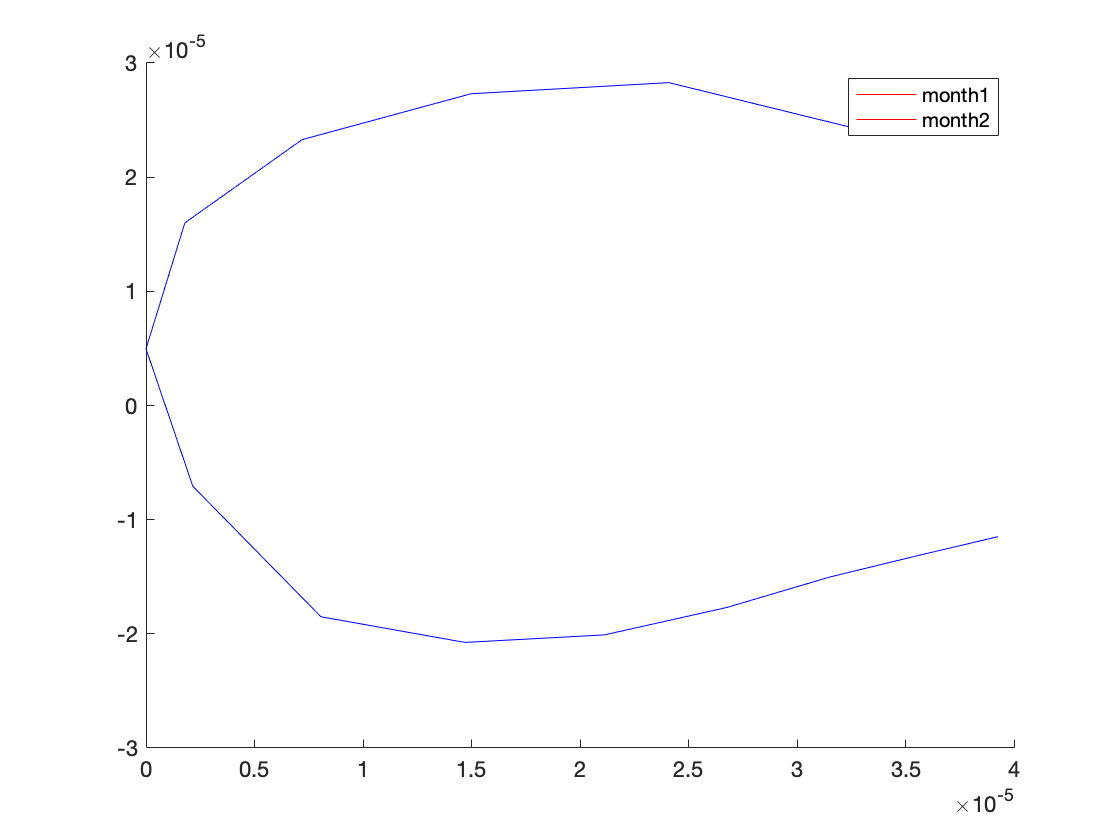

hold off
legend('month1', 'month2')

- figure 4.g.는 figure 2.o와 동일

- figure 4.e, h는 figure 2.o에서 FWHm만 signal power와 spikes count per neuron으로 바꾸면 됨

- figure 4.i 아직 이해 못함

- figure 5는 figure 2의 방법으로 모두 구현 가능